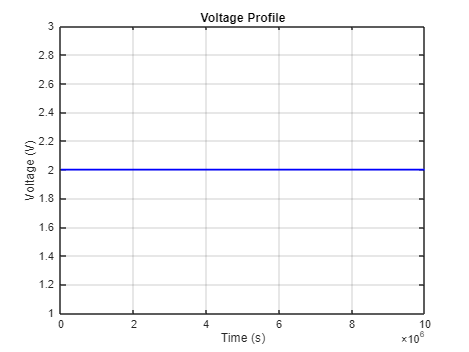

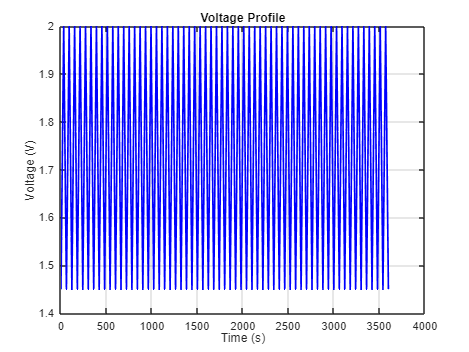

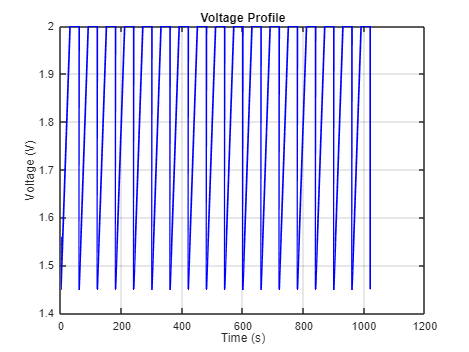

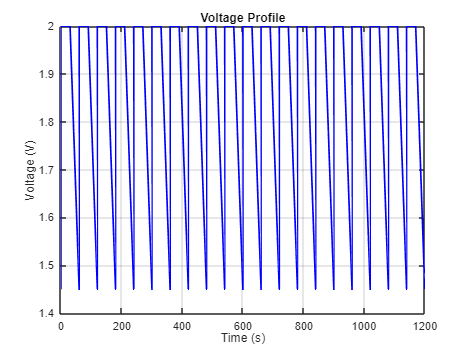

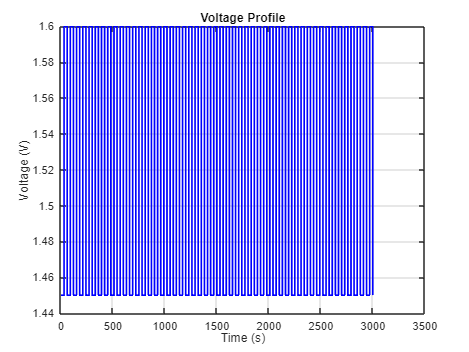

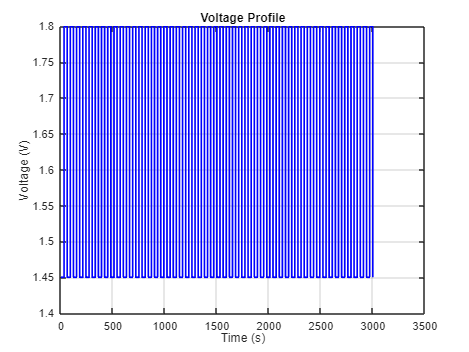

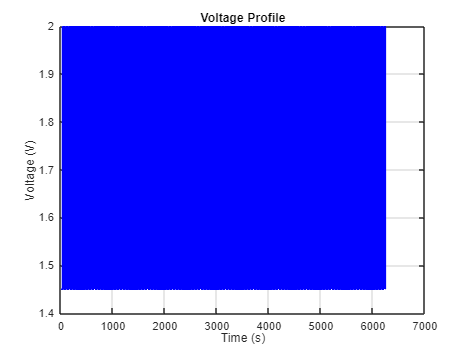

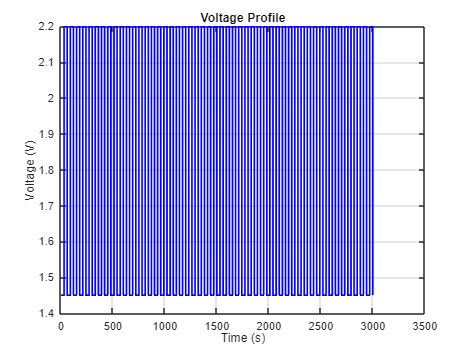

% ========================================================================
%  SIGNAL DYNAMISM VS. DEGRADATION ANALYSIS
%  This script processes multiple signal profiles, computes their
%  dynamism metrics using analyzeSignal(), normalizes them, and correlates
%  them with experimental degradation rates under various current densities.
% ========================================================================

% ------------------------------------------------------------------------
% File paths (Excel data files for each signal type)
% ------------------------------------------------------------------------
files = {
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\Hold.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\triangle.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\sawtooth_down.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\sawtooth_up.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_16V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_18V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_2V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_22V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_25V_60s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_2V_30s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_2V_20s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\square_2V_10s.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\solar.xlsx'
    'C:\Users\jaizpuru\Desktop\jon\ikerketa\experimental\Rainflow\wind.xlsx'
};

% ------------------------------------------------------------------------
% Initialize accumulator
% ------------------------------------------------------------------------
dynamism2_all = [];

% ------------------------------------------------------------------------
% Compute dynamism metrics for all signals
% ------------------------------------------------------------------------
for i = 1:length(files)
    filePath = files{i};
    [d1, d2, d3] = analyzeSignal(filePath);
    dynamism2_all = [dynamism2_all; d2];    
end

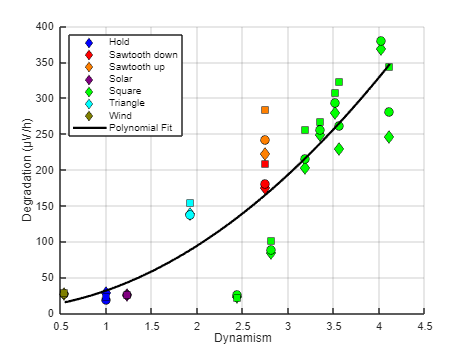


% ------------------------------------------------------------------------
% Dynamism normalization limits (they should be adapted if the input signal is
% an voltage, current density or power profile)
% ------------------------------------------------------------------------
limits = [2, 1.05, 10, 0.05, -0.05];

[n_rows, n_cols] = size(dynamism2_all);

% Initialize arrays
metric2_all = zeros(n_rows, 6);  % 5 normalized metrics + 1 total score
max_val_col1 = max(dynamism2_all(:, 1), [], 'omitnan');

% ------------------------------------------------------------------------
% Normalize metrics for each signal (it should be adapted if
% the input signal is an voltage, current density or power profile, as the
% voltage minimum is the OCV voltage but in curren density the minimum is
% 0)
% ------------------------------------------------------------------------
for i = 1:n_rows
    divisions = zeros(1, 5);
    
    % Column 1: Custom scaling (normalized between 0 and 1)
    current_val = dynamism2_all(i, 1);
    divisions(1) = (current_val - 1.45) / (max_val_col1 - 1.45);
    divisions(1) = min(max(divisions(1), 0), 1);
    
    % Columns 2, 4, and 5: normalized by predefined limits
    divisions([2 4 5]) = dynamism2_all(i, [2 4 5]) ./ limits([2 4 5]);
    
    % Column 3: inverse normalization (smaller period → higher score)
    divisions(3) = limits(3) / dynamism2_all(i, 3);
    
    % Clip values above 1
    divisions(divisions > 1) = 1;
    
    % Store metrics and total sum
    metric2_all(i, 1:5) = divisions;
    metric2_all(i, 6) = sum(divisions, 'omitnan');
end

% Final dynamism metric
metric2 = metric2_all(:, 6);

% ------------------------------------------------------------------------
% Experimental degradation rates (μV/h) for each current density
% ------------------------------------------------------------------------
degradation_05 = [28.3809524, 138.5714, 174.6667, 222.095, 22.8572, 84.7619, ...
         202.8571, 229.5238, 246.667, 249.5238, 279.4286, 369.5238, ...
         25.4629, 27.777];

degradation_1 = [19.4285714, 137.5238, 180.381, 242.2857, 26.0952, 88.7619, ...
          215.619, 261.7142, 281.1428, 255.619, 293.5238, 380.5714, ...
          26.0185, 27.639];

degradation_175 = [23.4285714, 154.2857, 208.5714, 284, 21.9048, 101.9048, ...
          256.19, 322.8571, 343.8095, 267.619, 307.619, NaN, 25.6944, 28.472];

% ------------------------------------------------------------------------
% Signal types and color mapping
% ------------------------------------------------------------------------
signal_type = {'Hold', 'Triangle', 'Sawtooth down', 'Sawtooth up', ...
               'Square', 'Square', 'Square', 'Square', ...
               'Square', 'Square', 'Square', 'Square', ...
               'Solar', 'Wind'};

color_map = containers.Map( ...
    {'Hold', 'Sawtooth down', 'Sawtooth up', 'Solar', 'Square', 'Triangle', 'Wind'}, ...
    {[0 0 1], [1 0 0], [1 0.5 0], [0.5 0 0.5], [0 1 0], [0 1 1], [0.5 0.5 0]});

unique_types = unique(signal_type);

% ------------------------------------------------------------------------
% SCATTER PLOTS: Dynamism vs. Degradation (per signal type)
% ------------------------------------------------------------------------
figure;
hold on;

for i = 1:length(unique_types)
    type = unique_types{i};
    idx = strcmp(signal_type, type);
    c = color_map(type);

    % 0.5 A/cm² → diamond
    scatter(metric2(idx), degradation_05(idx), 60, 'd', ...
        'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, ...
        'DisplayName', type);

    % 1 A/cm² → circle
    scatter(metric2(idx), degradation_1(idx), 60, 'o', ...
        'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, ...
        'HandleVisibility', 'off');

    % 1.75 A/cm² → square
    scatter(metric2(idx), degradation_175(idx), 60, 's', ...
        'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, ...
        'HandleVisibility', 'off');
end

xlabel('Dynamism');
ylabel('Degradation (μV/h)');
legend('Location', 'Northwest');
grid on;

% ------------------------------------------------------------------------
% Combine all data for regression fitting
% ------------------------------------------------------------------------
metric2 = metric2(:);
degradation_05 = degradation_05(:);
degradation_1 = degradation_1(:);
degradation_175 = degradation_175(:);

x_all = [];
y_all = [];

% 0.5 A/cm²
valid_05 = ~isnan(metric2) & ~isnan(degradation_05);
x_all = [x_all; metric2(valid_05)];
y_all = [y_all; degradation_05(valid_05)];

% 1 A/cm²
valid_1 = ~isnan(metric2) & ~isnan(degradation_1);
x_all = [x_all; metric2(valid_1)];
y_all = [y_all; degradation_1(valid_1)];

% 1.75 A/cm²
valid_175 = ~isnan(metric2) & ~isnan(degradation_175);
x_all = [x_all; metric2(valid_175)];
y_all = [y_all; degradation_175(valid_175)];

% ------------------------------------------------------------------------
% Polynomial fit (2nd order)
% ------------------------------------------------------------------------
p = polyfit(x_all, y_all, 2);
x_fit = linspace(min(x_all), max(x_all), 200);
y_fit = polyval(p, x_fit);

% Plot fitted curve
plot(x_fit, y_fit, 'k-', 'LineWidth', 2, 'DisplayName', 'Polynomial Fit');

% ------------------------------------------------------------------------
% FINAL PLOT SETTINGS
% ------------------------------------------------------------------------
xlabel('Dynamism');
ylabel('Degradation (μV/h)');
legend('Location', 'Northwest');
grid on;